theta1=0;d1=0;a1=10;alpha1=0; %parameter link1
theta2=0;d2=0;a2=10;alpha2=0; %parameter link2
theta3=0;d3=0;a3=5;alpha3=0; %parameter link3
T01=DHmatrix(theta1,d1,a1,alpha1);
T12=DHmatrix(theta2,d2,a2,alpha2);
T23=DHmatrix(theta3,d3,a3,alpha3);
T02=T01*T12;
T03=T01*T12*T23

T03 =      1     0     0    25
     0     1     0     0
     0     0     1     0
     0     0     0     1


theta1 = -331.734+360;
theta2 = 123.120;
theta3 = 573.349-360;
T01=DHmatrix(theta1,d1,a1,alpha1);
T12=DHmatrix(theta2,d2,a2,alpha2);
T23=DHmatrix(theta3,d3,a3,alpha3);
endq = [theta1, theta2, theta3]

endq =    28.2660  123.1200  213.3490


T02=T01*T12;
T03=T01*T12*T23

T03 =     0.9966   -0.0825         0    5.0119
    0.0825    0.9966         0    9.9375
         0         0    1.0000         0
         0         0         0    1.0000


P0 =      0     0     0


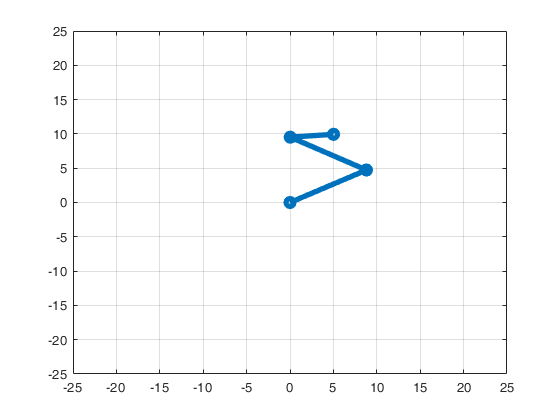

 
r = 
 
noname:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         10|          0|          0|
|  2|         q2|          0|         10|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


P1=transpose(T01(1:2,4));
P2=transpose(T02(1:2,4));
P3=transpose(T03(1:2,4));
Q1=[P0(1,1) P1(1,1) P2(1,1) P3(1,1)];
Q2=[P0(1,2) P1(1,2) P2(1,2) P3(1,2)];
plot(Q1,Q2,'-o','LineWidth',4);
axis([-25,25,-25,25]);

DH_(1) = Link([0 0 10 0]);
DH_(2) = Link([0 0 10 0]);
th_1 = (0:0.05:pi) ;
th_2 = (-pi:0.05:pi);
q_ = {th_1, th_1};
plotworkspace(DH_,q_)

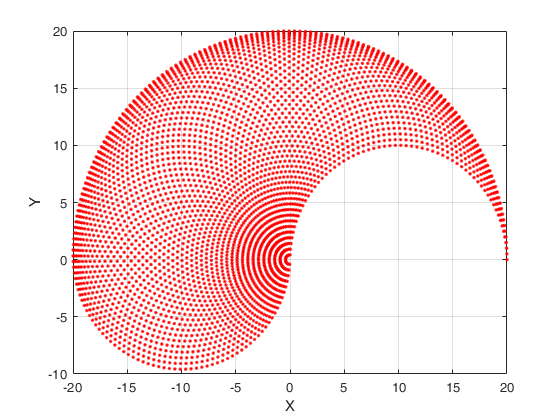

 
r = 
 
noname:: 3 axis, RRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         10|          0|          0|
|  2|         q2|          0|         10|          0|          0|
|  3|         q3|          0|          5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


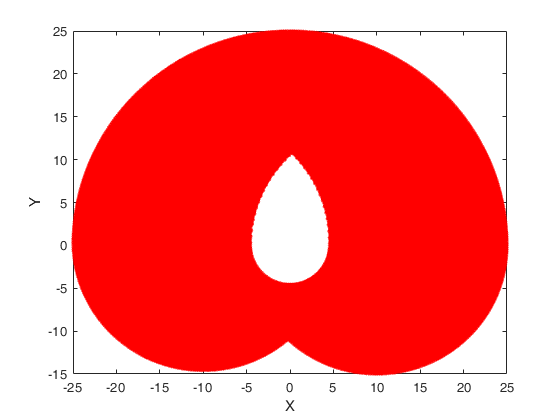


DH(1) = Link([0 0 10 0]);
DH(2) = Link([0 0 10 0]);
DH(3) = Link([0 0 5 0]);
th1 = (0:0.05:pi) ;
th2 = (-pi:0.05:pi);
th3 = (-pi/6:0.05:pi/6);
q = {th1, th2, th3};
plotworkspace(DH,q)

clc
clear
l(1) = Link([0,0.478, 0, -pi/2])
l(2) = Link([0, 0, 0.05, 0]);
l(3) = Link([0, 0, 0.05, -pi/2]);
% l(4) = Link([0, 0.425, 0, pi/2]);
% l(5) = Link([0, 0, 0, -pi/2]);
% l(6) = Link([0, 0.425, 0, 0]);
% l(7) = Link([0, 0.100, 0, 0]);
staubli = SerialLink(l)
cIKTE = staubli.fkine([0 0]);
staubli.plot([0, pi/3]);

clc
clear
syms q1 q2 real
l_(1) = Link([0, 0.478, 0, pi/2])

 
l_ = 
Revolute(std): theta=q, d=0.478, a=0, alpha=1.5708, offset=0


l_(2) = Link([0, 0.05, 0.425, 0]);
l_(3) = Link([0, 0, 0, -pi/2]);
l_(4) = Link([0, 0.425, 0, pi/2]);
l_(5) = Link([0, 0, 0, -pi/2]);
l_(6) = Link([0, 0.100, 0, 0]);
staubli_rtb = SerialLink(l_, 'name', 'staubli_rtb')

 
staubli_rtb = 
 
staubli_rtb:: 6 axis, RRRRRR, stdDH, slowRNE                     
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.478|          0|     1.5708|          0|
|  2|         q2|       0.05|      0.425|          0|          0|
|  3|         q3|          0|          0|    -1.5708|          0|
|  4|         q4|      0.425|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|        0.1|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


clkTE = staubli_rtb.fkine([0 0 0 0 0 0])

 

clkTE = 
         1         0         0     0.425
         0         1         0     -0.05
         0         0         1     1.003
         0         0         0         1


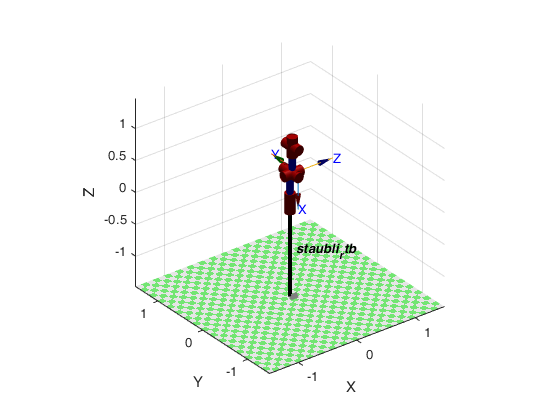

staubli_rtb.plot([0, pi/2, pi/2, 0, pi/2, 0]);

syms theta alpha a d l1 real
test(1) = Link([theta, d, a, alpha])

 
test = 
Revolute(std): theta=q, d=d, a=a, alpha=alpha, offset=0


one_link = SerialLink(test, 'name', 'one_link');
clkTE = one_link.fkine([theta])

$$\left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

clc
clear
theta1=0;d1=0;a1=0;alpha1=0; %parameter link1
theta2=0;d2=0.478;a2=0;alpha2=-pi/2; %parameter link2
theta3=0;d3=0.425;a3=0.05;alpha3=0; %parameter link3
T01=DHmatrix(theta1,d1,a1,alpha1);
T12=DHmatrix(theta2,d2,a2,alpha2);
T23=DHmatrix(pi/3,d3,a3,alpha3);
T02=T01*T12

T02 =     1.0000    0.0274         0         0
         0    0.9996         0         0
         0   -0.0274    0.9996    0.4780
         0         0         0    1.0000


T03=T01*T12*T23

T03 =     1.0003    0.0274   -0.0005    0.0500
    0.0183    0.9995   -0.0183    0.0009
   -0.0005   -0.0274    1.0001    0.9028
         0         0         0    1.0000
